# Latency analysis

clc; clear; close all;

## Dataset name

Enter below the dataset name. The file should contain a single json array.

fname_pub = 'public_sign.json';
fname_priv = 'private_sign.json';

## Load data

Load the data into memory.

json_pub = load_data(fname_pub);
json_priv = load_data(fname_priv);

## Extract data

Save all the timings for machine.

[ids, mu_pub, std_pub] = analyse(json_pub);
[~, mu_priv, std_priv] = analyse(json_priv);

## Plot

Plot mean and standard deviation.

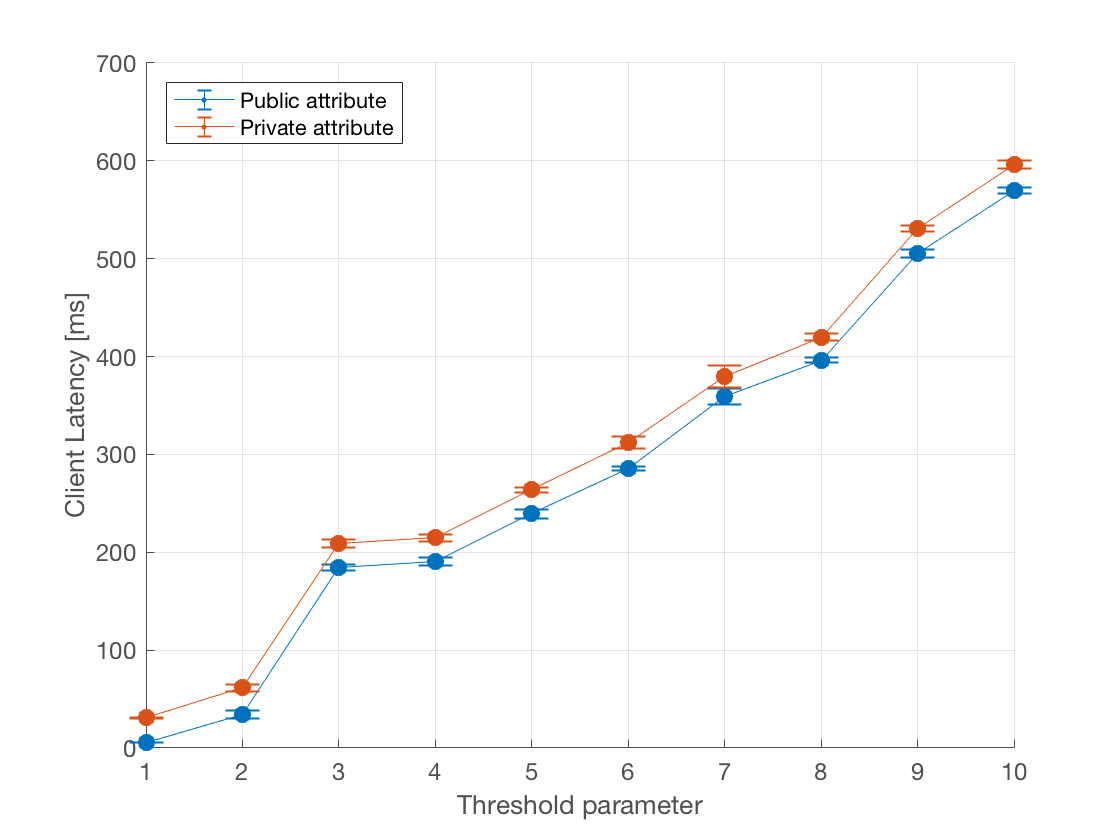

% plot mean and standard deviation
x = 1:length(ids);
createfigure([x' x'],[mu_pub' mu_priv' ],[std_pub' std_priv']);